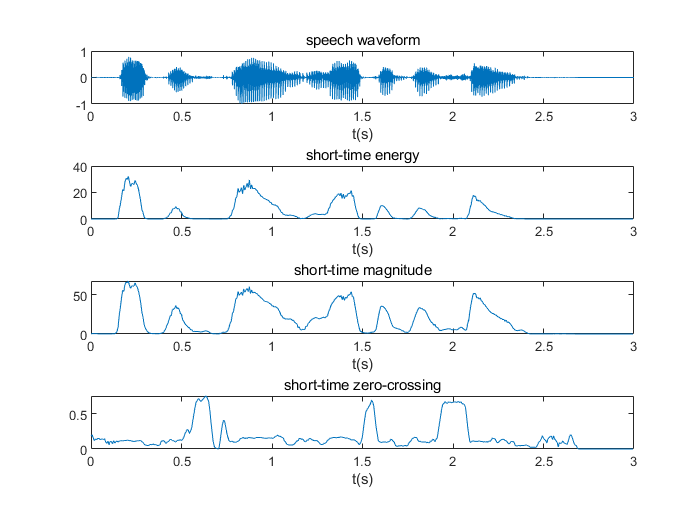

[s,fs]=audioread('s5.wav');
N=length(s);
L=201;
R1=round((L-1)/4);
R2=round((L-1)/2);
rectabgular=rectwin(L);
ham=hamming(L);
[E1,M1,Z1]=EMZ(s,L,R1,rectabgular);
[E2,M2,Z2]=EMZ(s,L,R2,rectabgular);
[E3,M3,Z3]=EMZ(s,L,R1,ham);
[E4,M4,Z4]=EMZ(s,L,R2,ham);

figure
subplot(4,1,1);
plot(0:1/fs:(N-1)/fs,s);
xlabel('t(s)');
title('speech waveform');
subplot(4,1,2);
plot(0:1/(fs/R1):(floor(N/R1)-1)/(fs/R1),E1);
xlabel('t(s)');
title('short-time energy');
subplot(4,1,3);
plot(0:1/(fs/R1):(floor(N/R1)-1)/(fs/R1),M1);
xlabel('t(s)');
title('short-time magnitude');
subplot(4,1,4);
plot(0:1/(fs/R1):(floor(N/R1)-1)/(fs/R1),Z1);
xlabel('t(s)');
title('short-time zero-crossing');

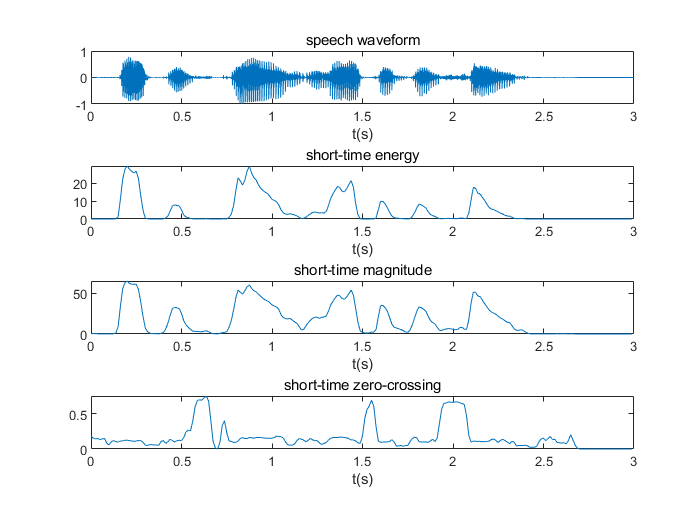


figure
subplot(4,1,1);
plot(0:1/fs:(N-1)/fs,s);
xlabel('t(s)');
title('speech waveform');
subplot(4,1,2);
plot(0:1/(fs/R2):(floor(N/R2)-1)/(fs/R2),E2);
xlabel('t(s)');
title('short-time energy');
subplot(4,1,3);
plot(0:1/(fs/R2):(floor(N/R2)-1)/(fs/R2),M2);
xlabel('t(s)');
title('short-time magnitude');
subplot(4,1,4);
plot(0:1/(fs/R2):(floor(N/R2)-1)/(fs/R2),Z2);
xlabel('t(s)');
title('short-time zero-crossing');

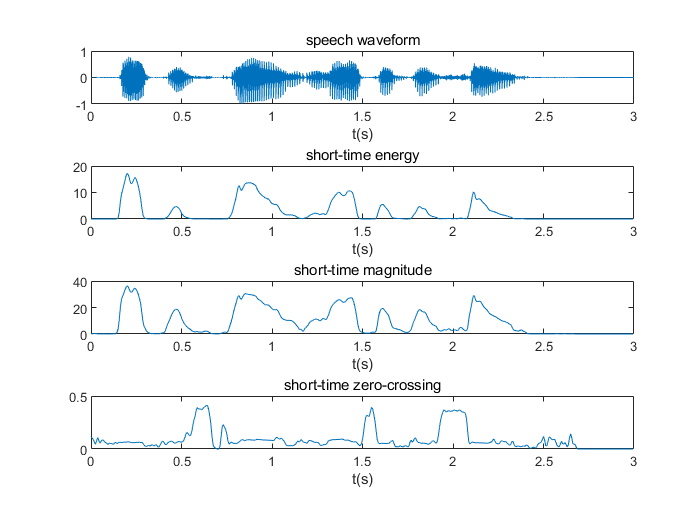


figure
subplot(4,1,1);
plot(0:1/fs:(N-1)/fs,s);
xlabel('t(s)');
title('speech waveform');
subplot(4,1,2);
plot(0:1/(fs/R1):(floor(N/R1)-1)/(fs/R1),E3);
xlabel('t(s)');
title('short-time energy');
subplot(4,1,3);
plot(0:1/(fs/R1):(floor(N/R1)-1)/(fs/R1),M3);
xlabel('t(s)');
title('short-time magnitude');
subplot(4,1,4);
plot(0:1/(fs/R1):(floor(N/R1)-1)/(fs/R1),Z3);
xlabel('t(s)');
title('short-time zero-crossing');

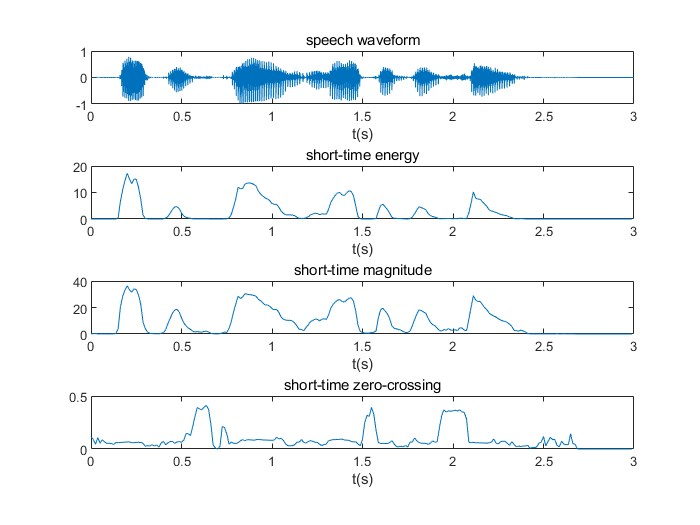


figure
subplot(4,1,1);
plot(0:1/fs:(N-1)/fs,s);
xlabel('t(s)');
title('speech waveform');
subplot(4,1,2);
plot(0:1/(fs/R2):(floor(N/R2)-1)/(fs/R2),E4);
xlabel('t(s)');
title('short-time energy');
subplot(4,1,3);
plot(0:1/(fs/R2):(floor(N/R2)-1)/(fs/R2),M4);
xlabel('t(s)');
title('short-time magnitude');
subplot(4,1,4);
plot(0:1/(fs/R2):(floor(N/R2)-1)/(fs/R2),Z4);
xlabel('t(s)');
title('short-time zero-crossing');